# FMCW Simulation for Radar-to-Radar interference

This simulation is based on the "Automotive Adaptive Cruise Control Using FMCW Technology" demo published by matlab. It has been modified to simulate the conditions for experiments being performed by the Duke CPSL using a TI IWR1443 mmWave radar

## FMCW Waveform

The following figure illustrates a typical FMCW "chirp"

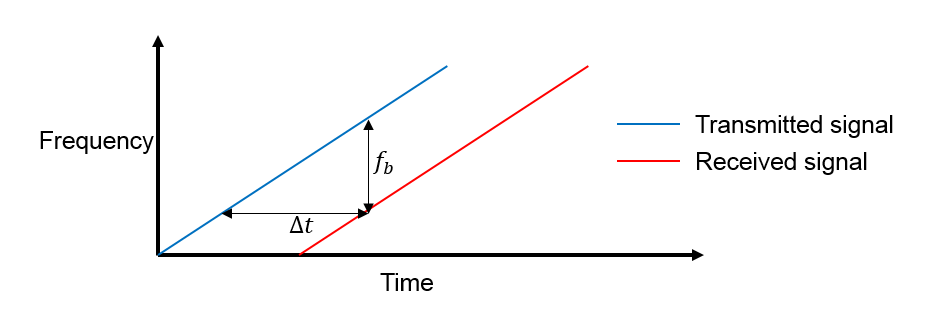

The received signal is a time-delayed copy of the transmitted signal where the delay, $\Delta t$, is related to the range. Because the signal is always sweeping through a frequency band, at any moment during the sweep, the frequency difference, $f_b$, is a constant between the transmitted signal and the received signal. $f_b$ is usually called the beat frequency. Because the sweep is linear, one can derive the time delay from the beat frequency and then translate the delay to the range.

### Defender Configuration

The FMCW configuration for the defender is as follows:

- Start frequency 77 GHz, end frequency 81 GHz

- Chirp cycle time - 72.98 us

- Chirp repition period - 145.96 us

- # of chirps - 32 chirps

- Frequency slope - 60 MHz

- Samples per chirp - 224

- Sampling rate - 3.817 Msps

- Sampling period - 58.68 us

- Sweep bandwidth (GHz) - 3.5211

This gives us the following predicted performance characteristics per the TI demo visualizer

- range resolution - 0.043 m

- max unambiguous range (m) - 8.19 m

- maximum radial velocity (m/s) - 4.01 m/s

- radial velocity resolution (m/s) - 0.51 m/s

Given these parameters, we configure defender radar using the following code:

Setting Parameters and obtaining performance from those values, (THESE WILL BE THE VALUES WHEN I USE THE IWR1443 VALUES)

% %key constants
% c = physconst('LightSpeed');
% 
% %key operating parameters
% fc = 77e9; 
% lambda = c/fc;
% fs = 3.817e6;
% samples_per_chirp = 224;
% tm = samples_per_chirp / fs; %sampling period
% chirp_repition_period = 145.96e-6
% %range calculations
% range_max = 8.1;
% sweep_slope = Fs*c/(2*range_max);
% sweep_slope_MHz_us = sweep_slope / 1e12;
% fr_max = range2beat(range_max,sweep_slope,c)
% 
% %range resolution calculations
% range_res = 0.043;
% bw = rangeres2bw(range_res,c)
% tm = samples_per_chirp / Fs;
% tm_us = tm / 1e-6;
% 
% %velocity calculations
% v_max = 4.01;
% chirp_repition_period = lambda / (4 * v_max) /2
% fd_max = speed2dop(2 * v_max,lambda)
% fb_max = fr_max + fd_max;
% fs = max(2*fb_max,bw);

Setting Parameters the way Matlab says to set them

fc = 77e9;
c = physconst('LightSpeed');
lambda = c/fc;

The sweep time can be computed based on the time needed for the signal to travel the unambiguous maximum range. In general, for an FMCW radar system, the sweep time should be at least 5 to 6 times the round trip time. This example uses a factor of 5.5.

range_max = 200;
tm = 5.5*range2time(range_max,c);
tm_us = tm / 1e-6

tm_us = 7.3384

The sweep bandwidth can be determined according to the range resolution and the sweep slope is calculated using both sweep bandwidth and sweep time.

range_res = 1;
bw = range2bw(range_res,c)

bw = 149896229

sweep_slope = bw/tm;
sweep_slope_MHz_us = sweep_slope / 1e12

sweep_slope_MHz_us = 20.4263

Because an FMCW signal often occupies a huge bandwidth, setting the sample rate blindly to twice the bandwidth often stresses the capability of A/D converter hardware. To address this issue, one can often choose a lower sample rate. Two things can be considered here:

- For a complex sampled signal, the sample rate can be set to the same as the bandwidth.

- FMCW radars estimate the target range using the beat frequency embedded in the dechirped signal. The maximum beat frequency the radar needs to detect is the sum of the beat frequency corresponding to the maximum range and the maximum Doppler frequency. Hence, the sample rate only needs to be twice the maximum beat frequency.

In this example, the beat frequency corresponding to the maximum range is given by

fr_max = range2beat(range_max,sweep_slope,c)

fr_max = 2.7254e+07

In addition, the maximum speed of a traveling car is about 230 km/h. Hence the maximum Doppler shift and the maximum beat frequency can be computed as

v_max = 230*1000/3600;
fd_max = speed2dop(2*v_max,lambda);

fb_max = fr_max+fd_max;

This example adopts a sample rate of the larger of twice the maximum beat frequency and the bandwidth.

fs = max(2*fb_max,bw)

fs = 149896229

### Waveform Setup

Initialize the FMCW waveform

num_sweeps = 1;
waveform = phased.FMCWWaveform('SweepTime', tm,'SweepBandwidth', bw, 'SampleRate', fs,'NumSweeps',num_sweeps);

obtain a sample of the FMCW waveform and plot it

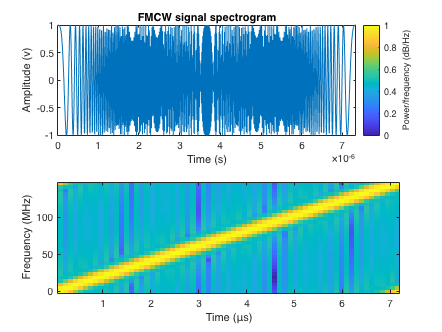

sig = waveform();
subplot(211); plot(0:1/fs:num_sweeps*tm-1/fs,real(sig));
xlabel('Time (s)'); ylabel('Amplitude (v)');
title('FMCW signal'); axis tight;
subplot(212); spectrogram(sig,32,16,32,fs,'yaxis');
title('FMCW signal spectrogram');

## Target Model

The target of an ACC radar is usually a car in front of it. This example assumes the target car is moving 50 m ahead of the car with the radar, at a speed of 96 km/h along the x-axis. 

The radar cross section of a car, according to [1], can be computed based on the distance between the radar and the target car.

car_dist = 43;
car_speed = 96*1000/3600;
car_rcs = db2pow(min(10*log10(car_dist)+5,20));

cartarget = phased.RadarTarget('MeanRCS',car_rcs,'PropagationSpeed',c,...
    'OperatingFrequency',fc);
carmotion = phased.Platform('InitialPosition',[car_dist;0;0.5],...
    'Velocity',[car_speed;0;0]);

The propagation model is assumed to be free space.

channel = phased.FreeSpace('PropagationSpeed',c,...
    'OperatingFrequency',fc,'SampleRate',fs,'TwoWayPropagation',true);

## Radar System Setup

The rest of the radar system includes the transmitter, the receiver, and the antenna. This example uses the parameters presented in [1]. Note that this example models only main components and omits the effect from other components, such as coupler and mixer. In addition, for the sake of simplicity, the antenna is assumed to be isotropic and the gain of the antenna is included in the transmitter and the receiver.

ant_aperture = 6.06e-4;                         % in square meter
ant_gain = aperture2gain(ant_aperture,lambda);  % in dB

tx_ppower = db2pow(5)*1e-3;                     % in watts
tx_gain = 9+ant_gain;                           % in dB

rx_gain = 15+ant_gain;                          % in dB
rx_nf = 4.5;                                    % in dB

transmitter = phased.Transmitter('PeakPower',tx_ppower,'Gain',tx_gain);
receiver = phased.ReceiverPreamp('Gain',rx_gain,'NoiseFigure',rx_nf,...
    'SampleRate',fs);

Automotive radars are generally mounted on vehicles, so they are often in motion. This example assumes the radar is traveling at a speed of 100 km/h along x-axis. So the target car is approaching the radar at a relative speed of 4 km/h.

radar_speed = 100*1000/3600;
radarmotion = phased.Platform('InitialPosition',[0;0;0.5],...
    'Velocity',[radar_speed;0;0]);

## Radar Signal Simulation

As briefly mentioned in earlier sections, an FMCW radar measures the range by examining the beat frequency in the dechirped signal. To extract this frequency, a dechirp operation is performed by mixing the received signal with the transmitted signal. After the mixing, the dechirped signal contains only individual frequency components that correspond to the target range.

In addition, even though it is possible to extract the Doppler information from a single sweep, the Doppler shift is often extracted among several sweeps because within one pulse, the Doppler frequency is indistinguishable from the beat frequency. To measure the range and Doppler, an FMCW radar typically performs the following operations:

- The waveform generator generates the FMCW signal.

- The transmitter and the antenna amplify the signal and radiate the signal into space.

- The signal propagates to the target, gets reflected by the target, and travels back to the radar.

- The receiving antenna collects the signal.

- The received signal is dechirped and saved in a buffer.

- Once a certain number of sweeps fill the buffer, the Fourier transform is performed in both range and Doppler to extract the beat frequency as well as the Doppler shift. One can then estimate the range and speed of the target using these results. Range and Doppler can also be shown as an image and give an intuitive indication of where the target is in the range and speed domain.

The next section simulates the process outlined above. A total of 64 sweeps are simulated and a range Doppler response is generated at the end.

During the simulation, a spectrum analyzer is used to show the spectrum of each received sweep as well as its dechirped counterpart.

specanalyzer = dsp.SpectrumAnalyzer('SampleRate',fs,...
    'PlotAsTwoSidedSpectrum',true,...
    'Title','Spectrum for received and dechirped signal',...
    'ShowLegend',true);

Next, run the simulation loop. 

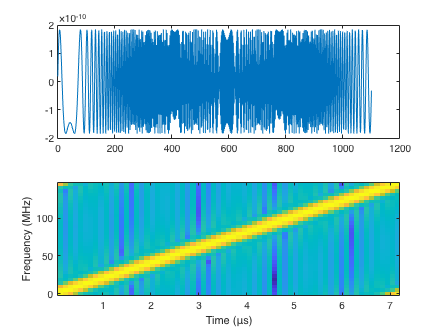

rng(2012);
Nsweep = 64;
xr = complex(zeros(waveform.SampleRate*waveform.SweepTime,Nsweep));

for m = 1:Nsweep
    % Update radar and target positions
    [radar_pos,radar_vel] = radarmotion(waveform.SweepTime);
    [tgt_pos,tgt_vel] = carmotion(waveform.SweepTime);

    % Transmit FMCW waveform
    sig = waveform();
    txsig = transmitter(sig);
    plot(real(txsig));
    
    % Propagate the signal and reflect off the target
    txsig = channel(txsig,radar_pos,tgt_pos,radar_vel,tgt_vel);
    plot(real(txsig));
    txsig = cartarget(txsig);
    plot(real(txsig));
    
    % Dechirp the received radar return
    txsig = receiver(txsig);
    plot(real(txsig));
    dechirpsig = dechirp(txsig,sig);
    
    % Visualize the spectrum
    specanalyzer([txsig dechirpsig]);
    
    xr(:,m) = dechirpsig;
end

## Radar Signal Simulation (with Attacker)

### Attacker Setup

Setting Parameters the way Matlab says to set them

Assumptions:

- Same chirp slope

- Same chirp period

- Same sampling rate - important

- same bandwidth

- same sweep time

Specify distance to add a point at and calculate the required time delay

desired_distance = 20; %m
time_delay = desired_distance/c %s

time_delay = 6.6713e-08

Specify the characteristics of the attack waveform

fc = 77e9;
c = physconst('LightSpeed');
lambda = c/fc;

The sweep time can be computed based on the time needed for the signal to travel the unambiguous maximum range. In general, for an FMCW radar system, the sweep time should be at least 5 to 6 times the round trip time. This example uses a factor of 5.5.

bw_attacker = bw; %same bandwidth
sweep_slope_attacker = sweep_slope; %same sweep slope
tm_attacker = bw/sweep_slope_attacker; %sweep time depends on bandwidth and sweep slope, currently same as defender
sweep_slope_MHz_us_attacker = sweep_slope_attacker / 1e12

sweep_slope_MHz_us_attacker = 20.4263

### Attacker Waveform Setup

Construct the delayed signal in matlab

%total number of samples should be the same as the defender
num_samples_attacker = num_sweeps * (tm*fs)

num_samples_attacker = 1100

num_samples_time_delay = time_delay*fs

num_samples_time_delay = 10

sig_attacker = zeros(num_samples_attacker,1);
size(sig_attacker)

ans =         1100           1


num_samples_waveform_attacker = num_samples_attacker - num_samples_time_delay;
waveform_attacker = phased.FMCWWaveform('SweepTime', tm_attacker,'SweepBandwidth', bw_attacker, 'SampleRate', fs,'OutputFormat','Samples',...
    'NumSamples',num_samples_waveform_attacker);

obtain a sample of the FMCW waveform and plot it

sig_attacker(num_samples_time_delay + 1:end,1) = waveform_attacker();
subplot(211); plot(0:1/fs:num_sweeps*tm-1/fs,real(sig_attacker));
xlabel('Time (s)'); ylabel('Amplitude (v)');
title('FMCW signal'); axis tight;
subplot(212); spectrogram(sig_attacker,32,16,32,fs,'yaxis');
title('FMCW signal spectrogram');

Plot the combined signals

combined_sig = sig_attacker + sig;
subplot(211); plot(0:1/fs:num_sweeps*tm-1/fs,real(combined_sig));
xlabel('Time (s)'); ylabel('Amplitude (v)');
title('FMCW signal - combined attacker and defender'); axis tight;
subplot(212); spectrogram(combined_sig,32,16,32,fs,'yaxis');
title('FMCW signal spectrogram - combined attacker and defender');

look at the dechirped output of these signals

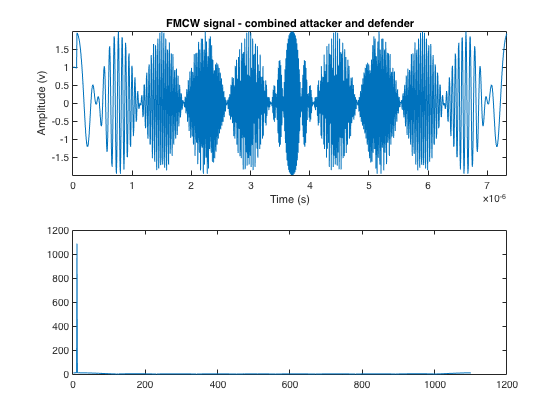

% Dechirp the received radar return
dechirpsig = dechirp(sig_attacker,sig);

% Visualize the spectrum
plot(abs(fft(dechirpsig)))

specanalyzer([sig dechirpsig]);

### Simulation Setup

As briefly mentioned in earlier sections, an FMCW radar measures the range by examining the beat frequency in the dechirped signal. To extract this frequency, a dechirp operation is performed by mixing the received signal with the transmitted signal. After the mixing, the dechirped signal contains only individual frequency components that correspond to the target range.

In addition, even though it is possible to extract the Doppler information from a single sweep, the Doppler shift is often extracted among several sweeps because within one pulse, the Doppler frequency is indistinguishable from the beat frequency. To measure the range and Doppler, an FMCW radar typically performs the following operations:

- The waveform generator generates the FMCW signal.

- The transmitter and the antenna amplify the signal and radiate the signal into space.

- The signal propagates to the target, gets reflected by the target, and travels back to the radar.

- The receiving antenna collects the signal.

- The received signal is dechirped and saved in a buffer.

- Once a certain number of sweeps fill the buffer, the Fourier transform is performed in both range and Doppler to extract the beat frequency as well as the Doppler shift. One can then estimate the range and speed of the target using these results. Range and Doppler can also be shown as an image and give an intuitive indication of where the target is in the range and speed domain.

The next section simulates the process outlined above. A total of 64 sweeps are simulated and a range Doppler response is generated at the end.

During the simulation, a spectrum analyzer is used to show the spectrum of each received sweep as well as its dechirped counterpart.

specanalyzer = dsp.SpectrumAnalyzer('SampleRate',fs,...
    'PlotAsTwoSidedSpectrum',true,...
    'Title','Spectrum for received and dechirped signal',...
    'ShowLegend',true);

Next, run the simulation loop. 

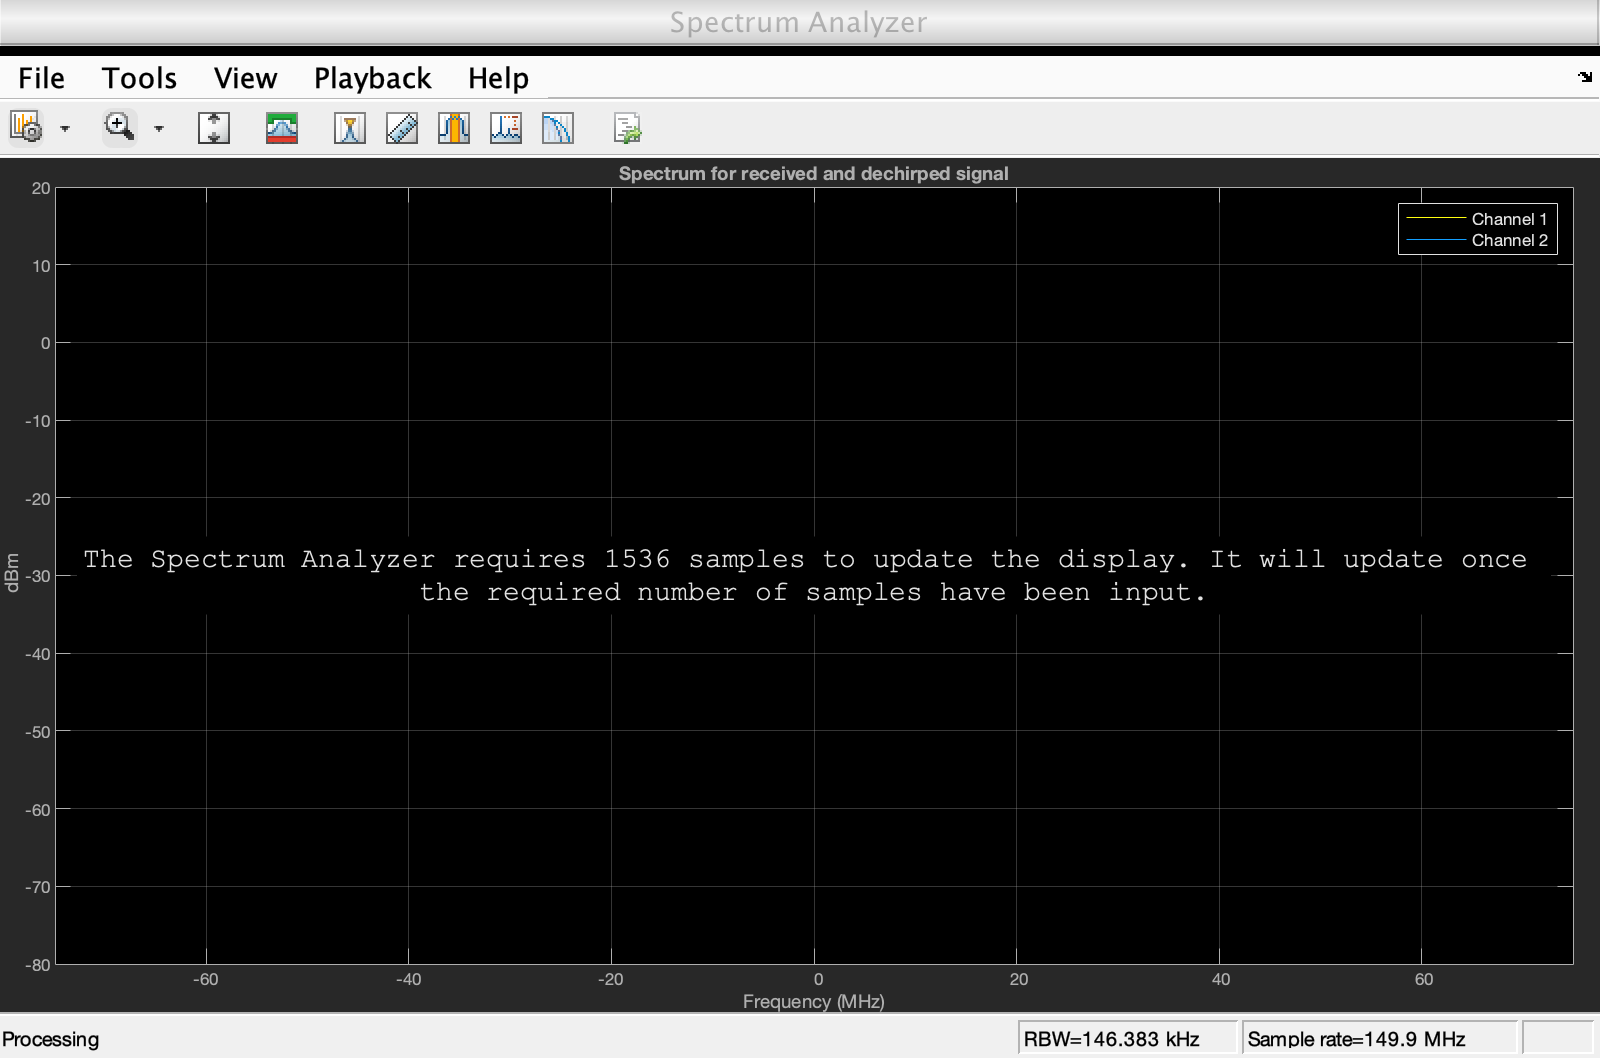

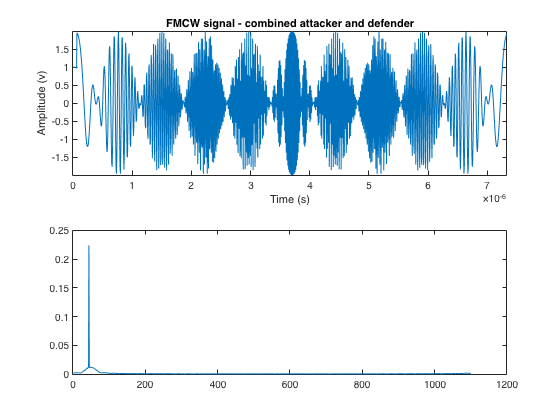

tx_gain_dB(2012);
Nsweep = 64;
xr = complex(zeros(waveform.SampleRate*waveform.SweepTime,Nsweep));

for m = 1:Nsweep
    % Update radar and target positions
    [radar_pos,radar_vel] = radarmotion(waveform.SweepTime);
    [tgt_pos,tgt_vel] = carmotion(waveform.SweepTime);

    % Transmit FMCW waveform
    sig = waveform();
    txsig = transmitter(sig);
    
    % Propagate the signal and reflect off the target
    txsig = channel(txsig,radar_pos,tgt_pos,radar_vel,tgt_vel);
    txsig = cartarget(txsig);
    
    %add in the attacker signal
    txsig_attacker = transmitter(sig_attacker);
    txsig_attacker = channel(txsig_attacker, radar_pos, tgt_pos, radar_vel, tgt_vel);
    txsig = txsig_attacker + txsig; %how to add the two signals together?

    % Dechirp the received radar return
    txsig = receiver(txsig);
    dechirpsig = dechirp(txsig,sig);
    
    % Visualize the spectrum
    specanalyzer([txsig dechirpsig]);
    plot(abs(fft(dechirpsig)))
    
    xr(:,m) = dechirpsig;
end

## Range and Doppler Estimation

Before estimating the value of the range and Doppler, it may be a good idea to take a look at the zoomed range Doppler response of all 64 sweeps.

rngdopresp = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','SweepSlope',sweep_slope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',2048,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',256);

clf;
plotResponse(rngdopresp,xr);                     % Plot range Doppler map
axis([-v_max v_max 0 range_max])